clc; clear; close all;

% Cargar datos
data = readtable('Five_times_Kinematics_HT_Query_final.xlsx');

fprintf('Dimensiones del dataset: %d filas x %d columnas\n', size(data,1), size(data,2));

Dimensiones del dataset: 46 filas x 81 columnas


disp('Variables del dataset:');

Variables del dataset:


disp(data.Properties.VariableNames);

    {'reclutado'}    {'AgeGroup'}    {'BMI_Value'}    {'GroupName'}    {'x1_AAFEM'}    {'x2_AAFEM'}    {'x4_AAFEM'}    {'x5_AAFEM'}    {'x1_AAIEM'}    {'x2_AAIEM'}    {'x3_AAIEM'}    {'x4_AAIEM'}    {'x5_AAIEM'}    {'x2_AKFEM'}    {'x3_AKFEM'}    {'x4_AKFEM'}    {'x5_AKFEM'}    {'x1_AKAAM'}    {'x2_AKAAM'}    {'x3_AKAAM'}    {'x4_AKAAM'}    {'x1_AKIEM'}    {'x2_AKIEM'}    {'x3_AKIEM'}    {'x4_AKIEM'}    {'x5_AKIEM'}    {'x1_AHPFEM'}    {'x2_AHPFEM'}    {'x3_AHPFEM'}    {'x4_AHPFEM'}    {'x5_AHPFEM'}    {'x2_AHPAAM'}    {'x3_AHPAAM'}    {'x4_AHPAAM'}    {'x5_AHPAAM'}    {'x1_AHPIEM'}    {'x3_AHPIEM'}    {'x4_AHPIEM'}    {'x5_AHPIEM'}    {'x1_APTILTM'}    {'x2_APTILTM'}    {'x3_APTILTM'}    {'x4_APTILTM'}    {'x5_APTILTM'}    {'x1_APOBLIM'}    {'x2_APOBLIM'}    {'x3_APOBLIM'}    {'x4_APOBLIM'}    {'x1_APROTM'}    {'x2_APROTM'}    {'x3_APROTM'}    {'x4_APROTM'}    {'x5_APROTM'}    {'x1_ASPMLM'}    {'x2_ASPMLM'}    {'x3_ASPMLM'}    {'x4_ASPMLM'}    {'x5_ASPMLM'}    {'x2_ASPIEM'}    {'x3_AS


% Seleccionar columnas numéricas
isNum = varfun(@isnumeric, data, 'OutputFormat','uniform');
numericData = data(:, isNum);
X = table2array(numericData);
[n, p] = size(X);
fprintf('El dataset sin outliers tiene %d muestras y %d dimensiones.\n', n, p);

El dataset sin outliers tiene 46 muestras y 78 dimensiones.


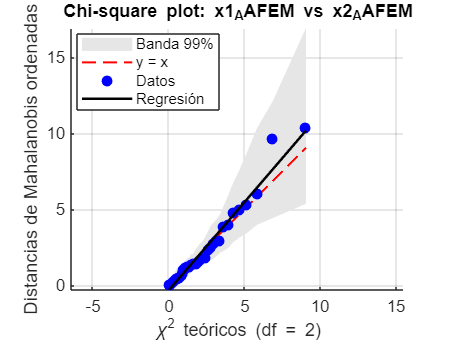

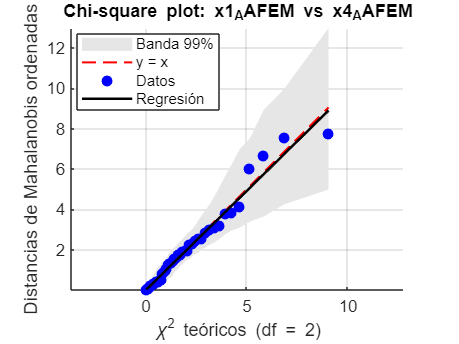

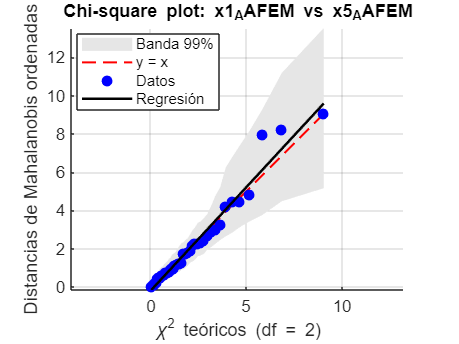

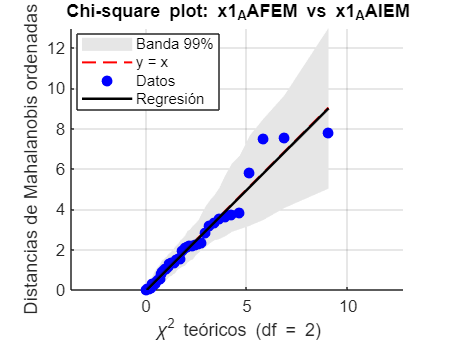

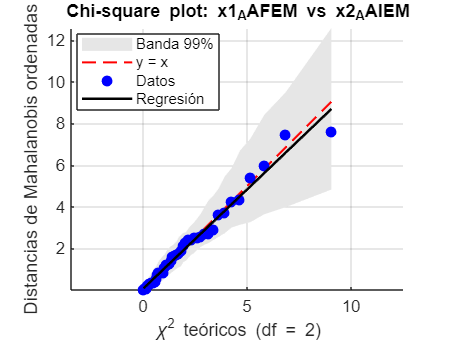

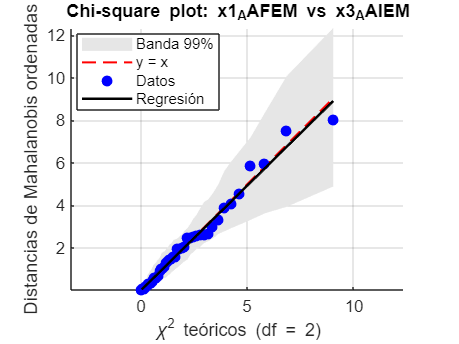

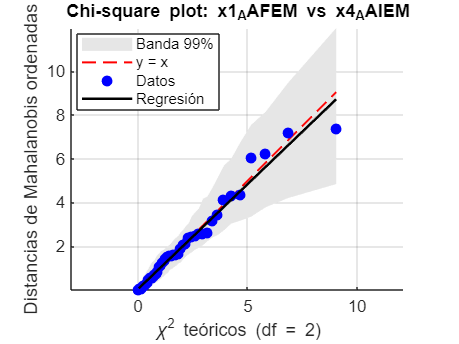

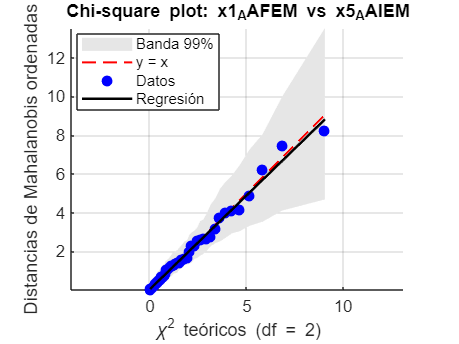


% Parámetros
B = 1000;
alpha = 0.01;
lower_p = alpha/2;
upper_p = 1 - alpha/2;
R2_threshold = 0.9632;

% Comparar variable 2 con todas las siguientes (desde la 3)
dim_interes = 76;

% Listas para resultados
var1_list_high = {}; var2_list_high = {}; slope_high = []; R2_high = [];
var1_list_low  = {}; var2_list_low  = {}; slope_low  = []; R2_low  = [];

for j = 77:p
    X_sub = [X(:, dim_interes), X(:, j)];
    mean_vec = mean(X_sub);
    cov_mat = cov(X_sub);
    inv_cov = pinv(cov_mat);

    % Distancias de Mahalanobis
    D2_obs = zeros(n,1);
    for i = 1:n
        d = X_sub(i,:) - mean_vec;
        D2_obs(i) = d * inv_cov * d';
    end
    D2_obs_sorted = sort(D2_obs);
    chi2_q = chi2inv(((1:n)' - 0.5) / n, 2);

    % Bootstrap no paramétrico
    D2_boot = zeros(n, B);
    for b = 1:B
        idx = randi(n, n, 1);
        Xb = X_sub(idx, :);
        mean_b = mean(Xb);
        cov_b = cov(Xb);
        inv_cov_b = pinv(cov_b);
        db_mat = Xb - mean_b;
        D2b = sum((db_mat * inv_cov_b) .* db_mat, 2);
        D2_boot(:,b) = sort(D2b);
    end
    lower_env = quantile(D2_boot, lower_p, 2);
    upper_env = quantile(D2_boot, upper_p, 2);

    % Ajuste lineal
    coeffs = polyfit(chi2_q, D2_obs_sorted, 1);
    y_fit = polyval(coeffs, chi2_q);
    R2 = corr(chi2_q, D2_obs_sorted)^2;

    % Guardar resultado en tablas
    varName_i = numericData.Properties.VariableNames{dim_interes};
    varName_j = numericData.Properties.VariableNames{j};

    if R2 >= R2_threshold
        var1_list_high{end+1} = varName_i;
        var2_list_high{end+1} = varName_j;
        slope_high(end+1) = coeffs(1);
        R2_high(end+1) = R2;
    else
        var1_list_low{end+1} = varName_i;
        var2_list_low{end+1} = varName_j;
        slope_low(end+1) = coeffs(1);
        R2_low(end+1) = R2;
    end

    % Gráfico
    figure;
    hold on;
    fill([chi2_q; flipud(chi2_q)], [lower_env; flipud(upper_env)], [0.9 0.9 0.9], 'EdgeColor','none');
    plot(chi2_q, chi2_q, 'r--', 'LineWidth',1.2);
    plot(chi2_q, D2_obs_sorted, 'bo', 'MarkerFaceColor','b');
    plot(chi2_q, y_fit, 'k-', 'LineWidth', 1.5);
    hold off;
    axis equal; grid on;
    xlabel('\chi^2 teóricos (df = 2)');
    ylabel('Distancias de Mahalanobis ordenadas');
    title(sprintf('Chi-square plot: %s vs %s', varName_i, varName_j));
    legend('Banda 99%', 'y = x', 'Datos', 'Regresión', 'Location', 'best');
end


% Crear tablas finales
tabla_R2_alto = table(var1_list_high', var2_list_high', slope_high', R2_high', ...
    'VariableNames', {'Variable_1', 'Variable_2', 'Pendiente', 'R2'});

tabla_R2_bajo = table(var1_list_low', var2_list_low', slope_low', R2_low', ...
    'VariableNames', {'Variable_1', 'Variable_2', 'Pendiente', 'R2'});

% Mostrar resultados
disp('============================================');

fprintf('>> Comparaciones con R² >= %.4f:\n', R2_threshold);

>> Comparaciones con R² >= 0.9632:


disp(tabla_R2_alto);

     Variable_1         Variable_2        Pendiente      R2   
    ____________    __________________    _________    _______

    {'x1_AAFEM'}    {'x2_AAFEM'      }      1.1643     0.96732
    {'x1_AAFEM'}    {'x4_AAFEM'      }     0.98305     0.97267
    {'x1_AAFEM'}    {'x5_AAFEM'      }      1.0814     0.96717
    {'x1_AAFEM'}    {'x2_AAIEM'      }      0.9549     0.98055
    {'x1_AAFEM'}    {'x3_AAIEM'      }     0.98516     0.98246
    {'x1_AAFEM'}    {'x4_AAIEM'      }     0.95799     0.97239
    {'x1_AAFEM'}    {'x5_AAIEM'      }     0.97064     0.98831
    {'x1_AAFEM'}    {'x2_AKFEM'      }     0.97798     0.96787
    {'x1_AAFEM'}    {'x3_AKFEM'      }     0.99996     0.96671
    {'x1_AAFEM'}    {'x5_AKFEM'      }     0.91416     0.97478
    {'x1_AAFEM'}    {'x1_AKAAM'      }      1.1179     0.96954
    {'x1_AAFEM'}    {'x3_AKAAM'      }      


fprintf('\n>> Comparaciones con R² < %.4f:\n', R2_threshold);


>> Comparaciones con R² < 0.9632:


disp(tabla_R2_bajo);

     Variable_1         Variable_2        Pendiente      R2   
    ____________    __________________    _________    _______

    {'x1_AAFEM'}    {'x1_AAIEM'      }     0.99769     0.96093
    {'x1_AAFEM'}    {'x4_AKFEM'      }      1.0195     0.94274
    {'x1_AAFEM'}    {'x2_AKAAM'      }       1.086     0.96298
    {'x1_AAFEM'}    {'x5_AKIEM'      }      1.0087     0.95746
    {'x1_AAFEM'}    {'x4_AHPFEM'     }      1.0579     0.96174
    {'x1_AAFEM'}    {'x3_ASHOBLIOFFM'}      1.0743     0.96125
    {'x1_AAFEM'}    {'x4_ASHROTOFFM' }      1.1166     0.96256
    {'x1_AAFEM'}    {'x5_ASHROTOFFM' }      1.1641     0.93397

